close all

## Question 3:1

As covered in the Matrix Inverses video, A square matrix is invertible if and only if both its columns and rows are linearly independent. By examining the rows and columns of Md, we discover that they are linearly independent, and hence an inverse must exist.

We discovered the matrix inverse to be the following: $M_d^{-1} =\left\lbrack \begin{array}{cccc}
1 & -d & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & -d\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

or, in matlab notation, Md = [1, -d, 0, 0; 0, 1, 0, 0; 0, 0, 1, -d; 0, 0, 0, 1];

This matrix is identical to Md except for the fact that the d values are negative.

## Question 3:2

The inverse matrix M^-1 is identical to the propagation matrix with a negative d value. This makes sense: as each ray is only represented by its propagation angle and position, the ray can move in two directions. You could then fully reconstruct the state of the ray at any distance d, whether positive or negative, from any one given state at any distance.

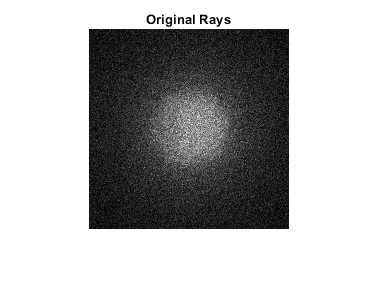

load("lightField.mat");
d = .2;
Md = [1, d, 0, 0; 0, 1, 0, 0; 0, 0, 1, d; 0, 0, 0, 1];
Minv = [1, -1*d, 0, 0; 0, 1, 0, 0; 0, 0, 1, -1*d; 0, 0, 0, 1];

rays0 = Md * rays;
rays1 = Minv * rays;

[img, x, y] = rays2img(rays(1, :), rays(3, :), 5*10^-3, 200);
imshow(img)
title('Original Rays')

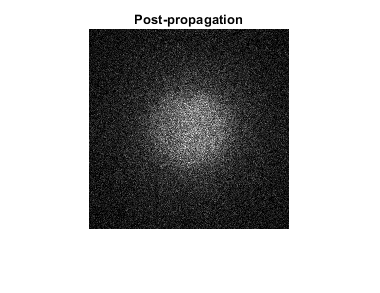


[img0, x0, y0] = rays2img(rays0(1, :), rays0(3, :), 5*10^-3, 200);
imshow(img0)
title('Post-propagation')

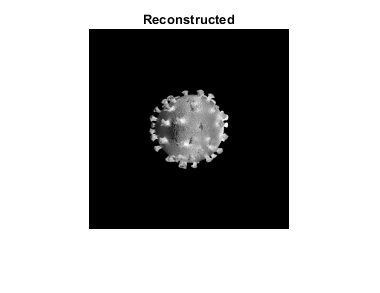


[img1, x1, y1] = rays2img(rays1(1, :), rays1(3, :), 5*10^-3, 200);
imshow(img1)
title("Reconstructed")